% Load and plot the old faithful data set
seedsData = dlmread('seeds.dat', '\t', 26, 0);
seedsData

seedsData =   13.020000000000000  13.760000000000000   0.864100000000000   5.395000000000000   3.026000000000000   3.373000000000000   4.825000000000000   1.000000000000000
  12.740000000000000  13.670000000000000   0.856400000000000   5.395000000000000   2.956000000000000   2.504000000000000   4.869000000000000   1.000000000000000
  14.109999999999999  14.180000000000000   0.882000000000000   5.541000000000000   3.221000000000000   2.754000000000000   5.038000000000000   1.000000000000000
  13.449999999999999  14.020000000000000   0.860400000000000   5.516000000000000   3.065000000000000   3.531000000000000   5.097000000000000   1.000000000000000
  13.160000000000000  13.820000000000000   0.866200000000000   5.454000000000000   2.975000000000000   0.855100000000000   5.056000000000000   1.000000000000000
  15.490000000000000  14.940000000000000   0.872400000000000   5.757000000000000   3.371000000000000   3.412000000000000   5.228000000000000   1.000000000000000
  14.090000000000000  

size(seedsData)

ans =    184     8


X = seedsData(:, [5,7])

X =    3.026000000000000   4.825000000000000
   2.956000000000000   4.869000000000000
   3.221000000000000   5.038000000000000
   3.065000000000000   5.097000000000000
   2.975000000000000   5.056000000000000
   3.371000000000000   5.228000000000000
   3.186000000000000   5.299000000000000
   3.150000000000000   5.012000000000000
   3.328000000000000   5.360000000000000
   3.485000000000000   5.443000000000000
   3.464000000000000   5.527000000000000
   3.683000000000000   5.484000000000000
   3.288000000000000   5.309000000000000
   3.298000000000000   5.001000000000000
   3.156000000000000   5.178000000000000
   3.158000000000000   5.176000000000000
   3.201000000000000   4.783000000000000
   3.396000000000000   5.528000000000000
   3.462000000000000   5.180000000000000
   3.155000000000000   4.961000000000000
   3.393000000000000   5.132000000000000
   3.377000000000000   5.175000000000000
   3.291000000000000   5.111000000000000
   3.258000000000000   5.351000000000000
   3.2720000

K = 3

K =      3


%%% Running kmeans many times and counting number of
% different solutions. 
% Kmeans converges to  locally optimal solutions that
% do not always correspond to the global optimum. 


ms1 =    2.978495495495495   5.100657657657658
   3.771897435897435   6.190333333333333
   3.551794117647059   5.789911764705883


e1 =   51.934675855366805


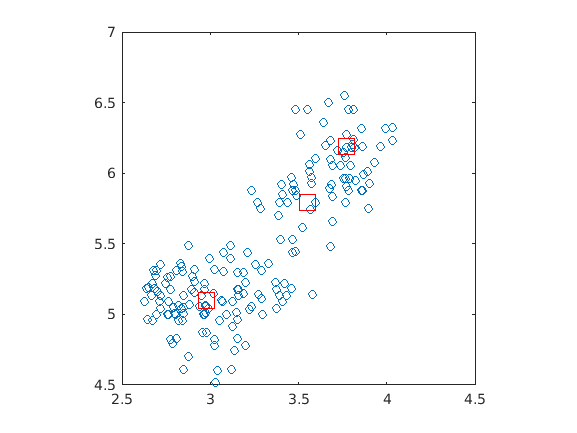

[ms1, e1] = analyzeKmeans(K, X) 

ms2 =    3.694984615384615   6.058246153846156
   3.290975000000000   5.288575000000002
   2.869177215189874   5.052202531645569


e2 =   52.551614462682799


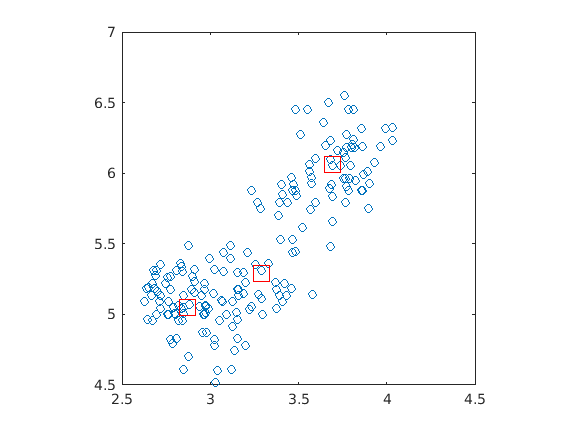

[ms2, e2] = analyzeKmeans(K, X) % second time

ms3 =    2.872412500000000   5.052687499999999
   3.295153846153846   5.293641025641027
   3.694984615384615   6.058246153846156


e3 =   52.551434663782125


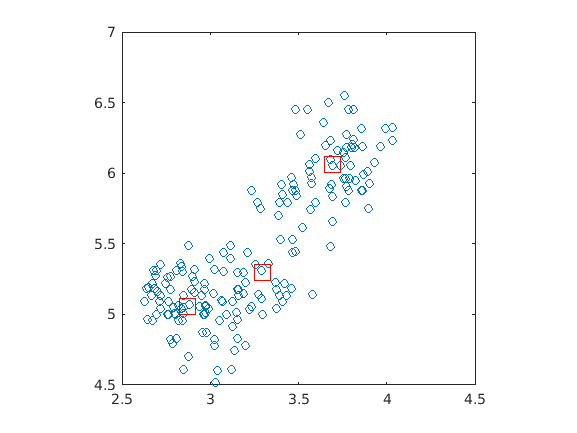

[ms3, e3] = analyzeKmeans(K, X) % different sol the third time

ms4 =    3.694984615384615   6.058246153846156
   3.290975000000000   5.288575000000002
   2.869177215189874   5.052202531645569


e4 =   52.551614462682799


[ms4, e4] = analyzeKmeans(K, X) % different than first time

ms5 =    3.771897435897435   6.190333333333333
   3.551794117647059   5.789911764705883
   2.978495495495495   5.100657657657658


e5 =   51.934675855366805


[ms5, e5] = analyzeKmeans(K, X)

ms6 =    3.694984615384615   6.058246153846156
   2.869177215189874   5.052202531645569
   3.290975000000000   5.288575000000002


e6 =   52.551614462682799


[ms6, e6] = analyzeKmeans(K, X)

ms7 =    2.872412500000000   5.052687499999999
   3.294475000000000   5.306175000000001
   3.701656249999999   6.062359375000002


e7 =   52.556309751562502


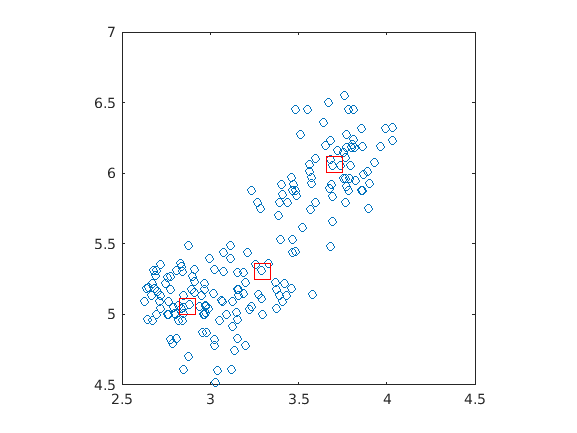

[ms7, e7] = analyzeKmeans(K, X)

ms8 =    2.872329113924051   5.047139240506328
   3.284341463414635   5.310682926829269
   3.701656249999999   6.062359375000002


e8 =   52.552738409585913


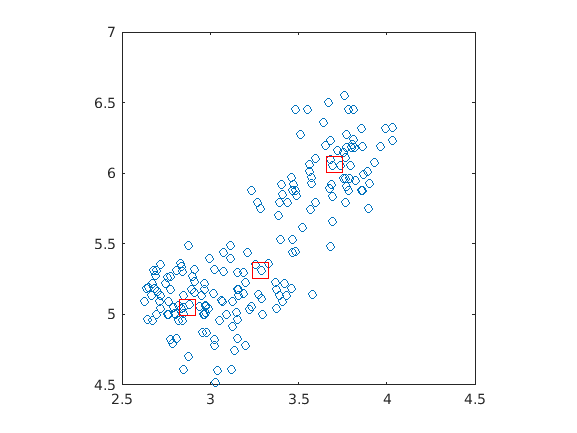

[ms8, e8] = analyzeKmeans(K, X)

ms9 =    2.869177215189874   5.052202531645569
   3.290975000000000   5.288575000000002
   3.694984615384615   6.058246153846156


e9 =   52.551614462682799


[ms9, e9] = analyzeKmeans(K, X)

ms10 =    3.290975000000000   5.288575000000002
   3.694984615384615   6.058246153846156
   2.869177215189874   5.052202531645569


e10 =   52.551614462682799


[ms10, e10] = analyzeKmeans(K, X)

ms11 =    3.284341463414635   5.310682926829269
   3.701656249999999   6.062359375000002
   2.872329113924051   5.047139240506328


e11 =   52.552738409585913


[ms11, e11] = analyzeKmeans(K, X)


% Observation: after running these several times, I got
% the first pair [ms1, e1] with lowest e1 = 51...
% and there were two means in the upper right cluser
% and one mean in the lower left, while all other
% plots have both means in the lower left cluster.

allEnergies = [e1, e2, e3, e4, e5, e6, e7, e8, e9, e10, e11]

allEnergies =   51.934675855366805  52.551614462682799  52.551434663782125  52.551614462682799  51.934675855366805  52.551614462682799  52.556309751562502  52.552738409585913  52.551614462682799  52.551614462682799  52.552738409585913



[minE, whichE] = min(allEnergies)

minE =   51.934675855366805


whichE =      1


ms2 =    3.694984615384615   6.058246153846156
   3.290975000000000   5.288575000000002
   2.869177215189874   5.052202531645569
